# **Etapa 2**

Para analizar los datos adquiridos por las antenas, primero es necesarios cargar el conjunto de datos.

filenames = dir('datos/*.txt');

Visualización del demo: Ahora visualizaremos la información proporcionada en el demo.

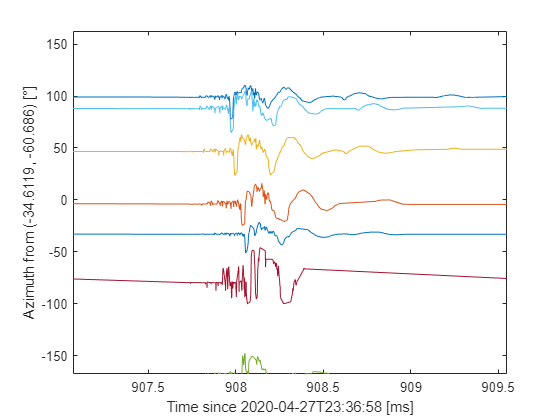

data = readtable(fullfile(filenames(1).folder, filenames(1).name));
corrected_time = table2array(data(2:end, 2));
signal = table2array(data(2:end, 4));

window = [1 1500;
    1501 2921;
    2921 4196;
    4198 4224;
    4226 6000;
    6000 7226;
    7227 8233;
    8234 9711];

figure,
for i = 1:8
    plot(corrected_time(window(i, 1):window(i, 2)), ...
        signal(window(i, 1):window(i, 2))), hold on
end
xlabel('Time since 2020-04-27T23:36:58 [ms]')
ylabel('Azimuth from (-34.6119, -60.686) [°]')
xlim([907 910])

De la figura se observa la distribución del la amplitud de la señal respecto a un breve periodo de tiempo (como se indicaba en la guía de la segunda etapa).

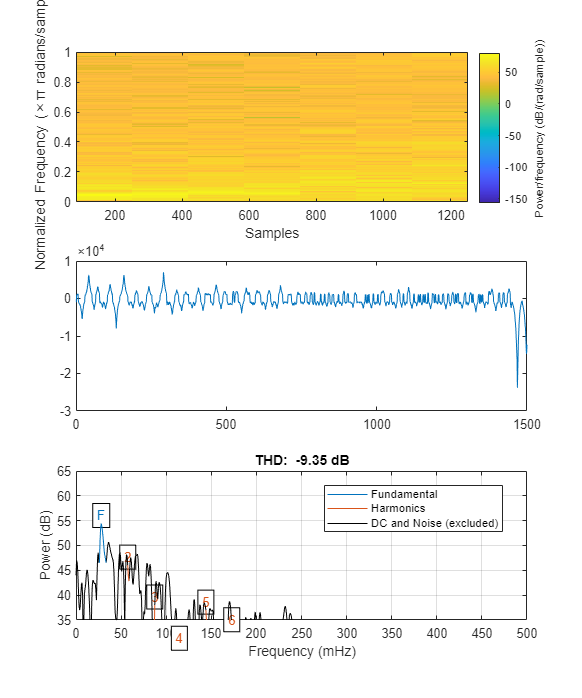

ans = -9.3453

figure('Renderer', 'painters', 'Position', [0, 0, 1000 1200])
subplot(311), spectrogram(signal(window(1, 1):window(1, 2)), 'yaxis')
subplot(312), plot(signal(window(1, 1):window(1, 2)))
subplot(313), thd(signal(window(1, 1):window(1, 2)))

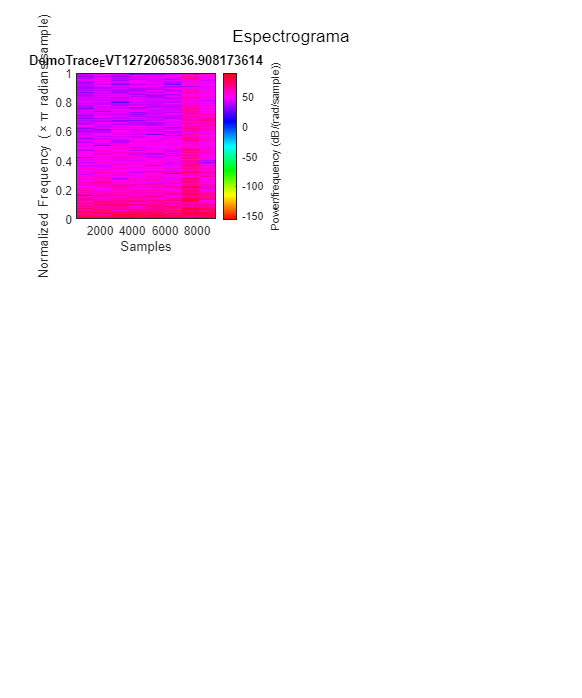

Unrecognized function or variable 'clim'.

figure('Renderer', 'painters', 'Position', [0, 0, 1000 1200])
sgtitle('Espectrograma') 
for i = 1:length(filenames)
    data = readtable(fullfile(filenames(i).folder, filenames(i).name));
    signal = table2array(data(2:end, 3));

    % player = audioplayer(signal / 24000, 5000);
    % play(player)
    
    subplot(3, 2, i), spectrogram(signal, 'yaxis'), title(erase(filenames(i).name, '.txt'))

end